# Black-Box Regression Example

The story stary with data:

clearvars; close all; clc;


load blackBoxData.mat

The first thing you may think about is the sampling time. Do we have equally spaced data? do we have missing data?

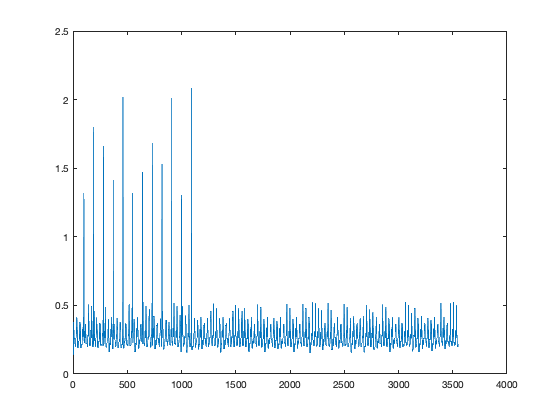

g = gradient(t);
plot(g)

The small oscillations (spiks) mostly indicate a non-equally spaced data. The large spikes is mostly indicate a missing data or large gap with no measurements.

For now, let us neglect the period with large gaps or missing data:

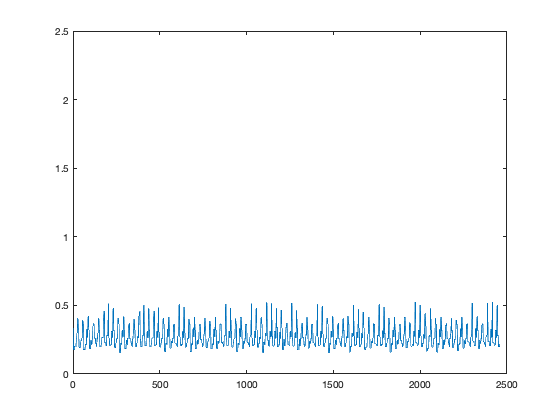

ix = find(g>1,1,'last');

X = X(ix+1:end,:);
t = t(ix+1:end);

g = gradient(t);
plot(g)
ylim([0 2.5]) %To be consistent with the previous figure

Now, we have the problem of non-equally spaced sampling. 

Take a look at the time series:

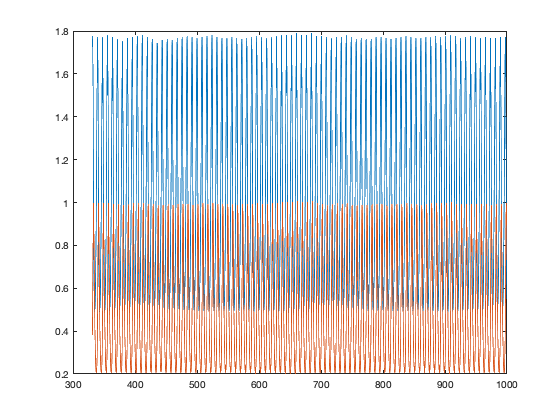

plot(t,X)

Since it is smooth curves, it is expected that the spline or cubic interpolation can do a good approximation:

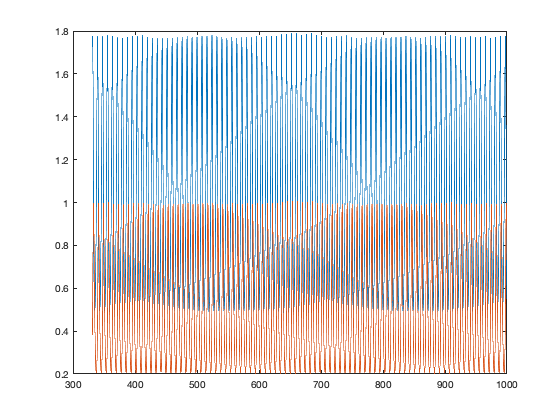

nt = linspace(min(t),max(t), 10*length(t)); %Re-create span of sampling time and 
                                            %  we increase number of measurements
                                            
Xn = zeros(length(nt),size(X,2)); %matrix to store interpolated data

Xn(:,1) = interp1(t,X(:,1),nt,"spline");
Xn(:,2) = interp1(t,X(:,2),nt,"spline");

plot(nt,Xn)

Now we start to prepare out data for data-driven modeling.

Xdot = (Xn(2:end,:)-Xn(1:end-1,:))./(nt(2)-nt(1)); %Estimated derivative.
Xn(end,:) = [];

Phi = x2fx(Xn,"quadratic"); %Assume the quadratic expansion
%See the documentation of the function x2fx wich have many options.


% In the least squares sense, our parameters are
B = pinv(Phi)*Xdot;

disp(B)

   -0.0251    0.0201
    0.7145   -0.0334
    0.0333   -1.0130
   -1.3501    0.9898
   -0.0225    0.0178
   -0.0130    0.0112



From here, you can apply regression methods to find the optimal parameters. Note that you apply the regression for each ODE separetely.

For example, if we choose lasso:

[B1, FitInfo] = lasso(Phi, Xdot(:,1), "CV",10);
B1 = B1(:,FitInfo.Index1SE);

[B2, FitInfo] = lasso(Phi, Xdot(:,2), "CV",10);
B2 = B2(:,FitInfo.Index1SE);


B = [B1, B2];

disp(B)

         0         0
    0.6009    0.0428
   -0.0882   -0.8631
   -1.2341    0.9100
         0         0
         0   -0.0452



Try other methods. Iterative hard thresholding for example. And remember that you apply the regression for each ode separetely. 